# Intrusion Detection

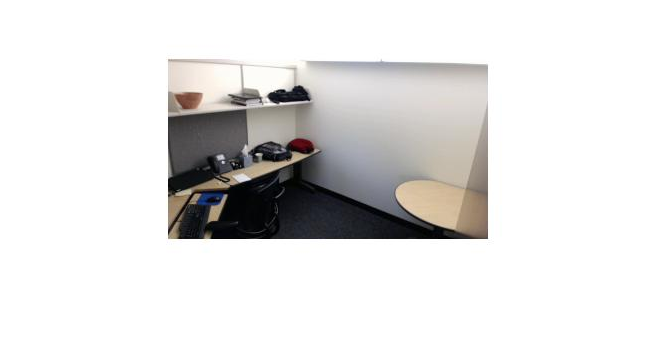

%% Read Images

im1 = imread('Image1.jpg');
im2 = imread('Image2.jpg');
figure; imshow(im1);

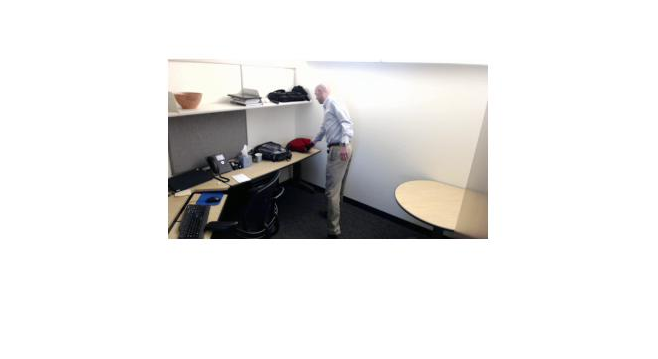

figure; imshow(im2);

## Convert to grayscale

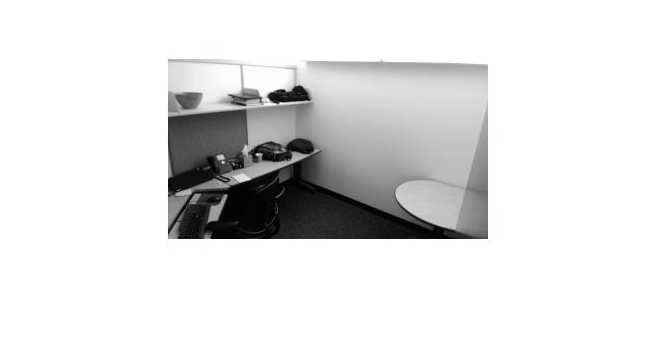

im1 = rgb2gray(im1);
im2 = rgb2gray(im2);
figure; imshow(im1);

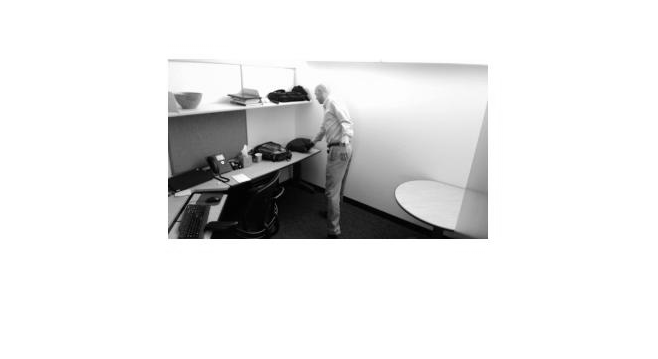

figure; imshow(im2);

## Substract Images

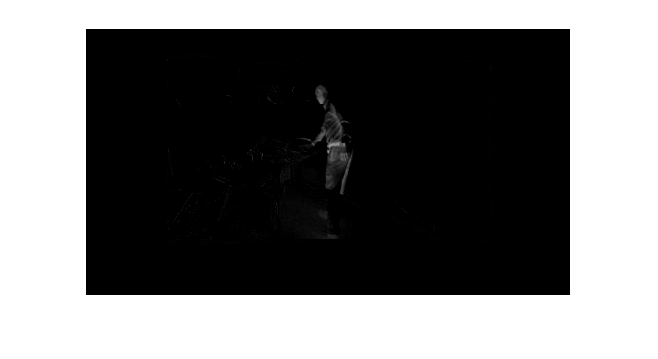

im_diff = abs(im1 - im2);
%im_diff = imsubtract(im1, im2);
figure; imshow(im_diff);

## Use imaging tools

%imtool(im_diff);
%imhist(im_diff);

## Thresholding

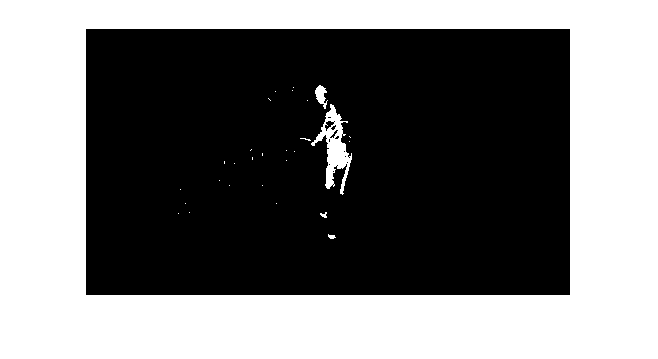

im_diff = im2double(im_diff);
th = graythresh(im_diff);
im_bin = im_diff > th;
%im_bin = imbinarize(im_diff);
figure; imshow(im_bin);

## Fill in Regions

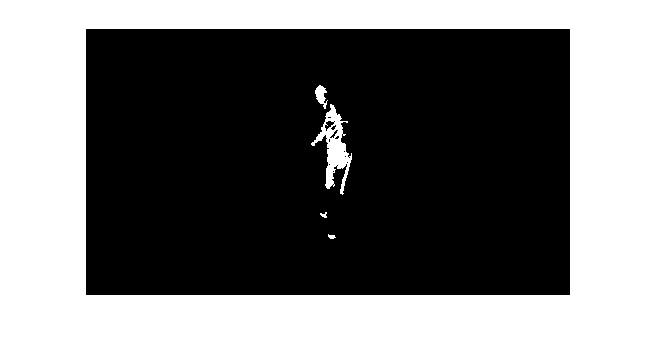

%se = strel('disk',1);
%im_open = imopen(im_bin, se);
im_open = bwareaopen(im_bin,15);
figure; imshow(im_open);

%% Connect Components (Region Properties)

im_stats = regionprops(im_open, 'MajoraxisLength');
im_length = [im_stats.MajorAxisLength];
idx = im_length > 80;
im_stats_final = im_stats(idx);
disp(im_stats_final)

    MajorAxisLength: 84.4839



if isempty(im_stats_final)
    disp('Nothing here')
else
    disp('There is something here')
end

There is something here
